# Flux balance analysis on an aerobic and anaerobic healthy GEM

*By: Michiel Adriaens, Maastricht Centre for Systems Biology, Maastricht University*

*Date: 3-11-2021*

## Introduction

In this interactive document, we will simulate the production of energy, i.e. ATP, under aerobic  and anaerobic conditions in a model of a healthy cell culture. 

The procedure for each simulation is the same. For each new simulation, the original model will be copied to a new variable. This preserves the constraints of the original model to perform further simulations with new constraints. Additionally, this method of renaming the model avoids confusion while performing multiple simulations at the same time.

*Note: This script is in part based on the FBA tutorial from COBRA: *[goo.gl/SvSAoQ](http://goo.gl/SvSAoQ)

## Section 0: Some preliminaries

Before we start the analyses, there are a couple of things we need to take care of. 

First, we need to browse to the folder containing all the practical materials by clicking on the open folder icon ( ) on the topleft of the Matlab menubar. Next, we we load the required Recon 2.2 model with the following code:

load('recon22.mat');


Let's have a look at the GEM:

recon22

recon22 = struct with fields:
        modelVersion: [1×1 struct]
                rxns: {7785×1 cell}
                mets: {5324×1 cell}
                   S: [5324×7785 double]
                 rev: [7785×1 double]
                   c: [7785×1 double]
            metNames: {5324×1 cell}
         metFormulas: {5324×1 cell}
                  lb: [7785×1 double]
                  ub: [7785×1 double]
           metCharge: [5324×1 double]
               rules: {7785×1 cell}
               genes: {1675×1 cell}
          rxnGeneMat: [7785×1675 double]
             grRules: {7785×1 cell}
          subSystems: {7785×1 cell}
    confidenceScores: {7785×1 cell}
       rxnReferences: {7785×1 cell}
        rxnECNumbers: {7785×1 cell}
            rxnNotes: {7785×1 cell}
            rxnNames: {7785×1 cell}
          metChEBIID: {5324×1 cell}
             metHMDB: {5324×1 cell}
           metKEGGID: {5324×1 cell}
        metPubChemID: {5324×1 cell}
      metInChIString: {5324×1 cell}
               

We can see several important elements that are present in the object:

- *rxns *= all reactions contained in the model

- *mets *= metabolites

- *S *= the stoichiometric matrix 

- *genes * = genes

Next, we need to start the COBRA toolbox (will take about 2 minutes to complete). We will additionally turn all warnings of for the time being:

warning('off','all');
initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2025
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.49.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

There are different solvers available to perform flux balance analysis. For this practical, we will simply stick to the default:

changeCobraSolver('glpk','all');

 > The compatibility can only be evaluated on Windows 7 and Windows 10.
 > The solver compatibility is not tested with MATLAB R2021b.
 > Solver for LP problems has been set to glpk.
 > The compatibility can only be evaluated on Windows 7 and Windows 10.
 > The solver compatibility is not tested with MATLAB R2021b.
 > Solver for MILP problems has been set to glpk.
 > Solver glpk not supported for problems of type MIQP. No solver set for this problemtype 
 > Solver glpk not supported for problems of type NLP. No solver set for this problemtype 
 > Solver glpk not supported for problems of type QP. No solver set for this problemtype 


## Section 1: Simulating cells growing in RPMI medium

Next, we will simulate cells growing in RPMI medium, but first:

- Have a look at the following page: [https://en.wikipedia.org/wiki/Roswell_Park_Memorial_Institute_medium](https://en.wikipedia.org/wiki/Roswell_Park_Memorial_Institute_medium) and [http://www.thermofisher.com/se/en/home/technical-resources/media-formulation.114.html](http://www.thermofisher.com/se/en/home/technical-resources/media-formulation.114.html) 

- Before running the code below, have a look at the script *RPMImediumSimulation.m* by double clicking on it in the file browser on the left.

**Question: You might recognize some of the components of the RPMI medium (based on the web links). What is the symbol used for glucose in the model?**

...

Now we will actually run the RPMI medium simulation to acquire a model for which metabolite concentrations are adapted to the RPMI medium contents. This output model is called *modelRPMI:*

model = recon22;
RPMImediumSimulation;
modelRPMI

modelRPMI = struct with fields:
        modelVersion: [1×1 struct]
                rxns: {7785×1 cell}
                mets: {5324×1 cell}
                   S: [5324×7785 double]
                 rev: [7785×1 double]
                   c: [7785×1 double]
            metNames: {5324×1 cell}
         metFormulas: {5324×1 cell}
                  lb: [7785×1 double]
                  ub: [7785×1 double]
           metCharge: [5324×1 double]
               rules: {7785×1 cell}
               genes: {1675×1 cell}
          rxnGeneMat: [7785×1675 double]
             grRules: {7785×1 cell}
          subSystems: {7785×1 cell}
    confidenceScores: {7785×1 cell}
       rxnReferences: {7785×1 cell}
        rxnECNumbers: {7785×1 cell}
            rxnNotes: {7785×1 cell}
            rxnNames: {7785×1 cell}
          metChEBIID: {5324×1 cell}
             metHMDB: {5324×1 cell}
           metKEGGID: {5324×1 cell}
        metPubChemID: {5324×1 cell}
      metInChIString: {5324×1 cell}
             

## Section 2: Perfom flux balance analysis (FBA) simulating aerobic conditions 

In this section we will simulate aerobic respiration using FBA, that is metabolism under conditions were oxygen is readily available.

Let's copy the RPMI model to a new variable called *modelaerobic*:

modelaerobic = modelRPMI;


FBA requires defining an 'objective': what should the metabolic aim to produce. In this case, we want to maximize the amount of ATP generation. For this we will use the ATP demand reaction, which is called *DM_atp_c_. *It is a reaction that involves hydrolysis of ATP to ADP, Pi and proton in the cytosol. Let's see what that looks like in Matlab code:

printRxnFormula(modelaerobic, 'DM_atp_c_');

DM_atp_c_	atp[c] + h2o[c] 	->	adp[c] + h[c] + pi[c] 


We will set this reaction as our objective with the *changeObjective* command. Maximising the flux through the ATP demand reaction will result in the network producing a maximal amount of ATP (up to the limit of the reaction):

modelaerobic = changeObjective(modelaerobic, 'DM_atp_c_');


The oxygen, in this case, will be provided in high amounts to the model for maximizing the flux through ATP demand. The *changeRxnBounds* function changes the flux constraints of the lower (*'l'*), upper (*'u'*), or both the bounds (*'b'*), of the specified reaction. 

Here, we will change: the maximal update of oxygen to 1000 *mol/min/gDW*. This means that the uptake of oxygen is effectively unconstrainted:

modelaerobic = changeRxnBounds(modelaerobic, 'EX_o2(e)', -1000, 'l');


To actually perform the FBA, we will use the function *optimizeCbModel.*This model calculates one of the optimal solutions for a (maximum or minimum) objective reaction within the defined solution space. In our current example, the maximal flux through the *DM_atp_c_* reaction is desired.

FBAaerobic = optimizeCbModel(modelaerobic, 'max');
FBAaerobic

FBAaerobic = struct with fields:
         full: [7785×1 double]
          obj: 1000
        rcost: [7785×1 double]
         dual: [5324×1 double]
        slack: [5324×1 double]
       solver: 'glpk'
    algorithm: 'default'
         stat: 1
     origStat: 5
         time: 0.4690
        basis: []
            x: [7785×1 double]
            f: 1000
            y: [5324×1 double]
            w: [7785×1 double]
            v: [7785×1 double]


We can inspect the result by looking at the component *obj* in the *FBAaerobic *object: 

FBAaerobic.obj

ans = 1000

**Question: What is the flux through the ATP demand reaction and how does it compare to the maximum of 1000? What does this mean biologically? **

...

## Section 3: Perfom flux balance analysis (FBA) simulating anaerobic conditions 

In this section we will simulate anaerobic respiration using FBA, that is metabolism under conditions were oxygen is **not** available.

Let's copy the RPMI model to a new variable called *modelanaerobic*:

modelanaerobic = modelRPMI;


The oxygen, in this case, will be **not** be provided to the model for maximizing the flux through ATP demand. Hence we will:

- Set the maximal update of oxygen to 0 *mol/min/gDW*, meaning that there is no uptake of oxygen!

modelanaerobic = changeRxnBounds(modelanaerobic, 'EX_o2(e)', 0, 'l');


Same as before, maximal flux through the *DM_atp_c_* reaction is desired as the objective of the model:

modelanaerobic = changeObjective(modelanaerobic,'DM_atp_c_');


And finally we will run FBA for thus constructed anaerobic model:

FBAanaerob = optimizeCbModel(modelanaerobic,'max');


We can inspect the result by looking at the component *obj* in the *FBAaerobic *object. The maximum throughput of the reaction is 1000. 

FBAanaerob.obj

ans = 69.5937

**Question: What is the flux through the ATP demand reaction and how does it compare to the flux in the aerobic case above? What does this mean biologically? **

...

## 4. Visualize the results

Finally we should visualize the results by visualizing the flux through reactions of interest. As an example, let's focus on all reactions involving lactic acid in the cytosol.

**Question: Via which reaction is lactic acid produced during respiration? Do you expect more or less production of lactic acid in the anaerobic model?**

...

Let's draw the result for the aerobic and anaerobic model. The '1' in the code below signifies that we only want reactions that directly involve lactic acid.

*IMPORTANT: SELECT THE FOLLOWING CODE AND PRESS F9:*

Start_time = '2025_6_27_21_47_35.729'

Biograph object with 55 nodes and 76 edges.


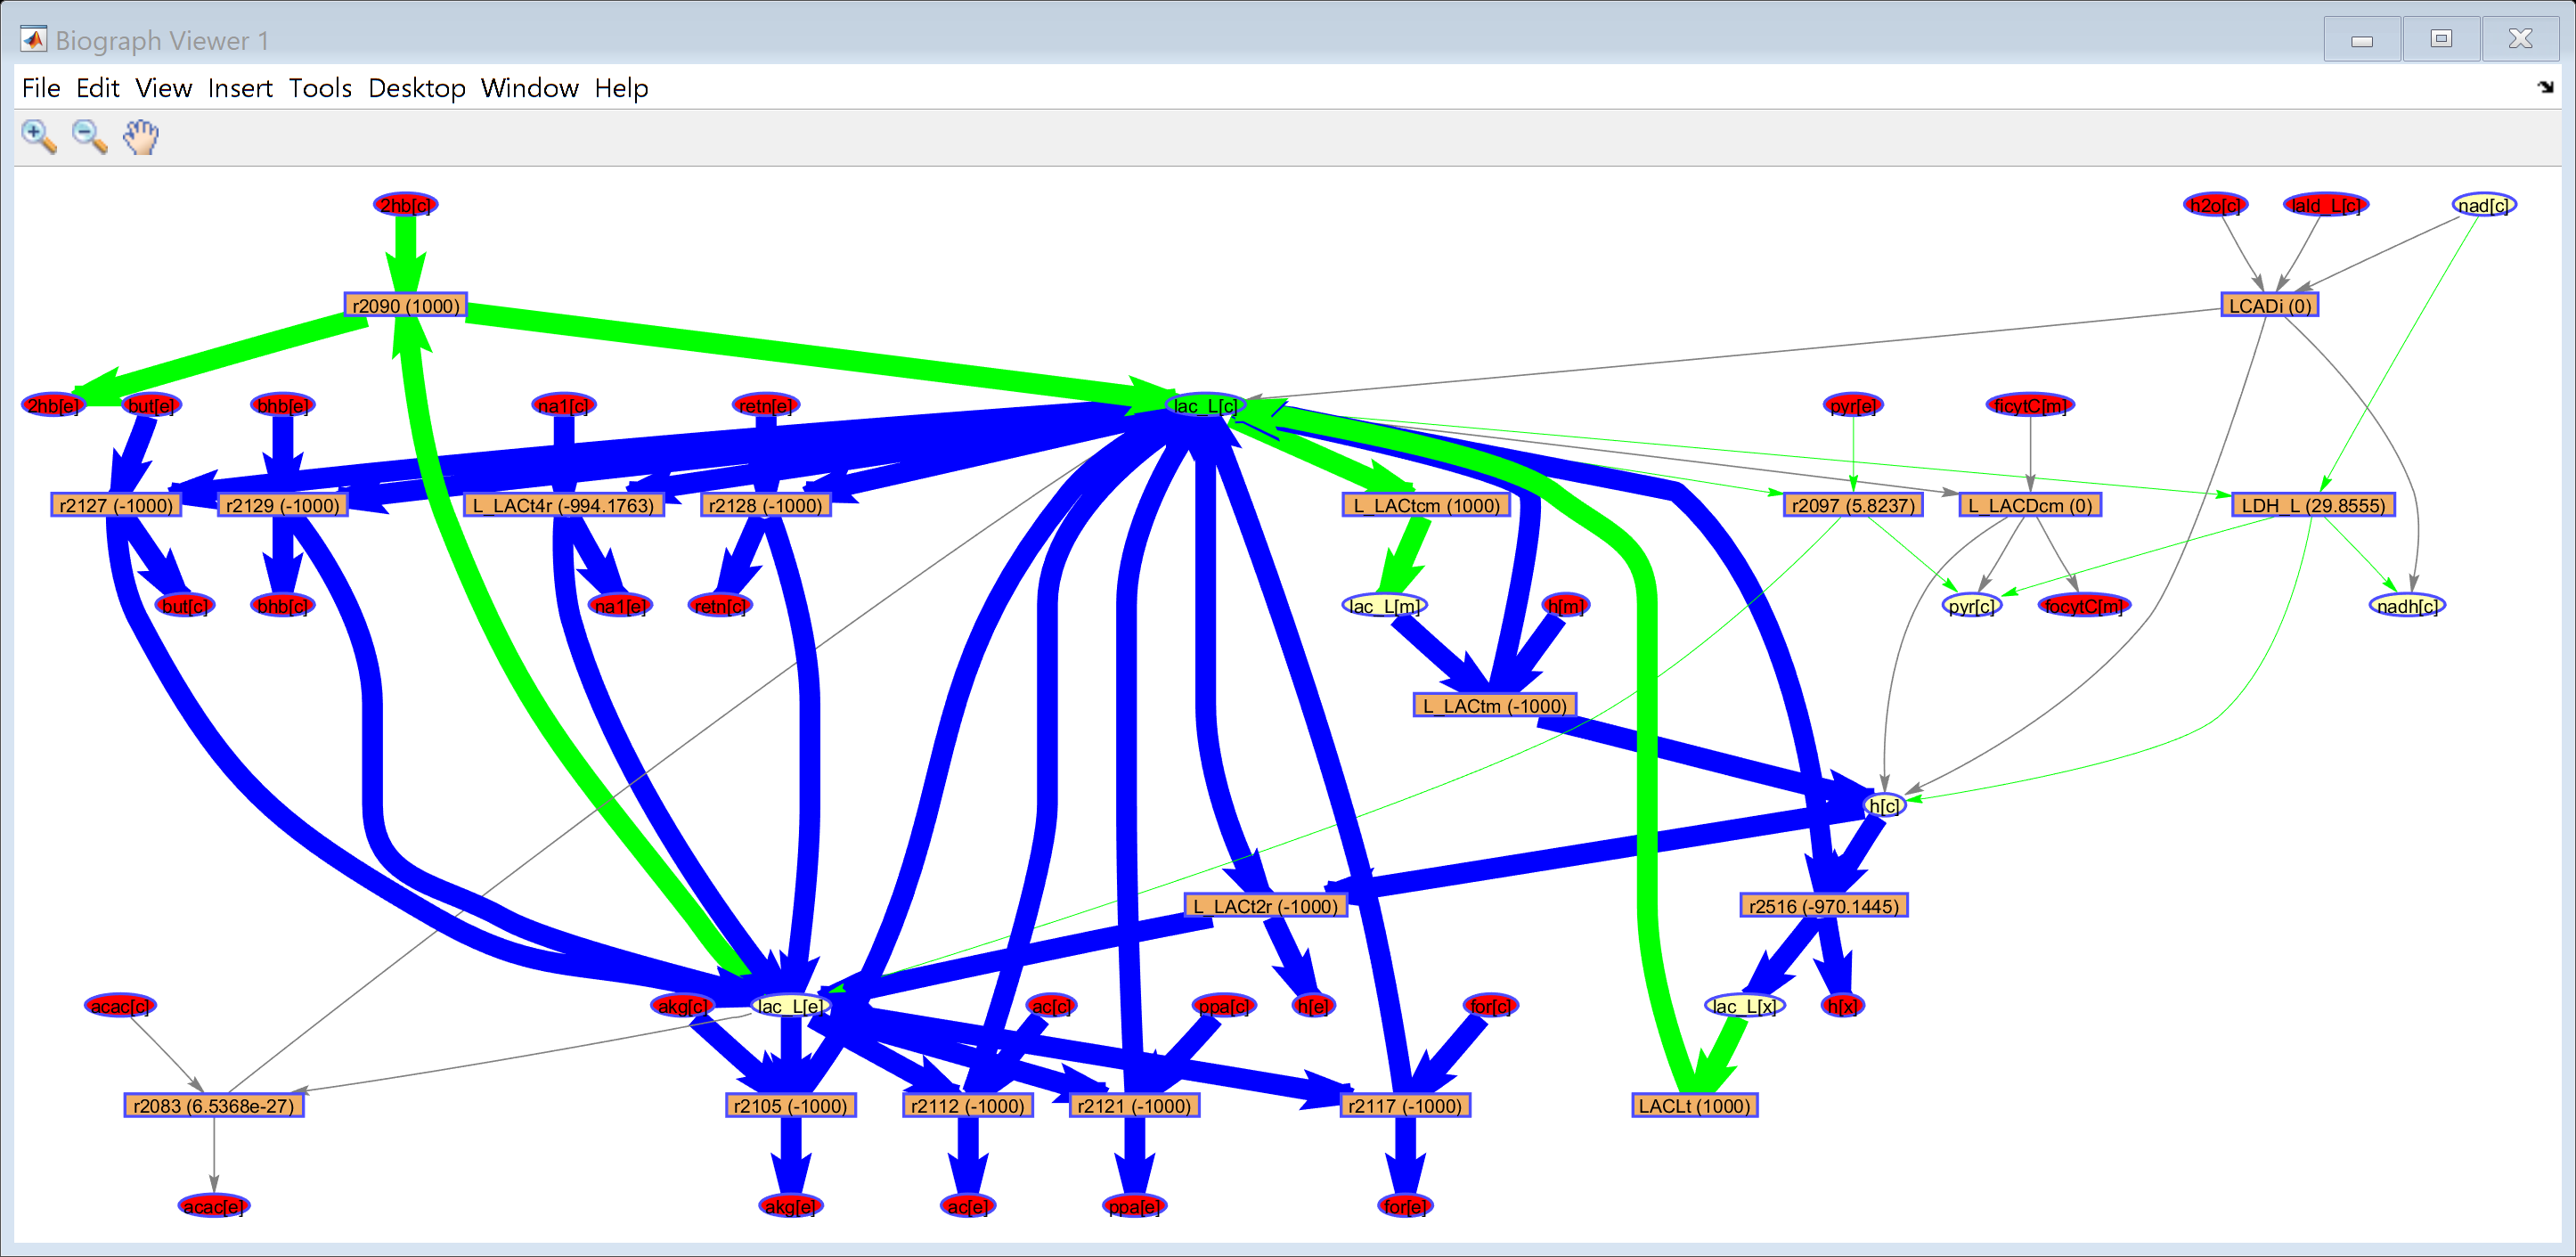

End_time = '2025_6_27_21_47_39.925'

Total_time = '0_0_0_0_0_4.196'

% Aerobic:
draw_by_met(model, {'lac_L[c]'}, 'true', 1, 'struc', {''}, FBAaerobic.v);

% Anaerobic:
draw_by_met(model, {'lac_L[c]'}, 'true', 1, 'struc', {''}, FBAanaerob.v);

Start_time = '2025_6_27_21_47_39.944'

Biograph object with 55 nodes and 76 edges.


End_time = '2025_6_27_21_47_43.84'

Total_time = '0_0_0_0_0_3.896'

Arrows show the direction of reaction input and output. Most reactions are reversible, hence flux can be positive and negative:

- The color ***blue*** indicates that the reaction to which the arrow is connected has a ***negative flux***

- The color ***green*** indicates that the reaction to which the arrow is connected has a ***positive flux***

**Questions: **

- **What is the name of the reaction producing lactic acid from pyruvate?**

- **What is the flux through this reaction in the aerobic model? And in the anaerobic model?**

- **Did you expect this difference from a biological perspective? Briefly explain.**

## **~ END OF SCRIPT ~**

Start_time = '2025_6_28_18_10_56.583'

Biograph object with 6 nodes and 5 edges.


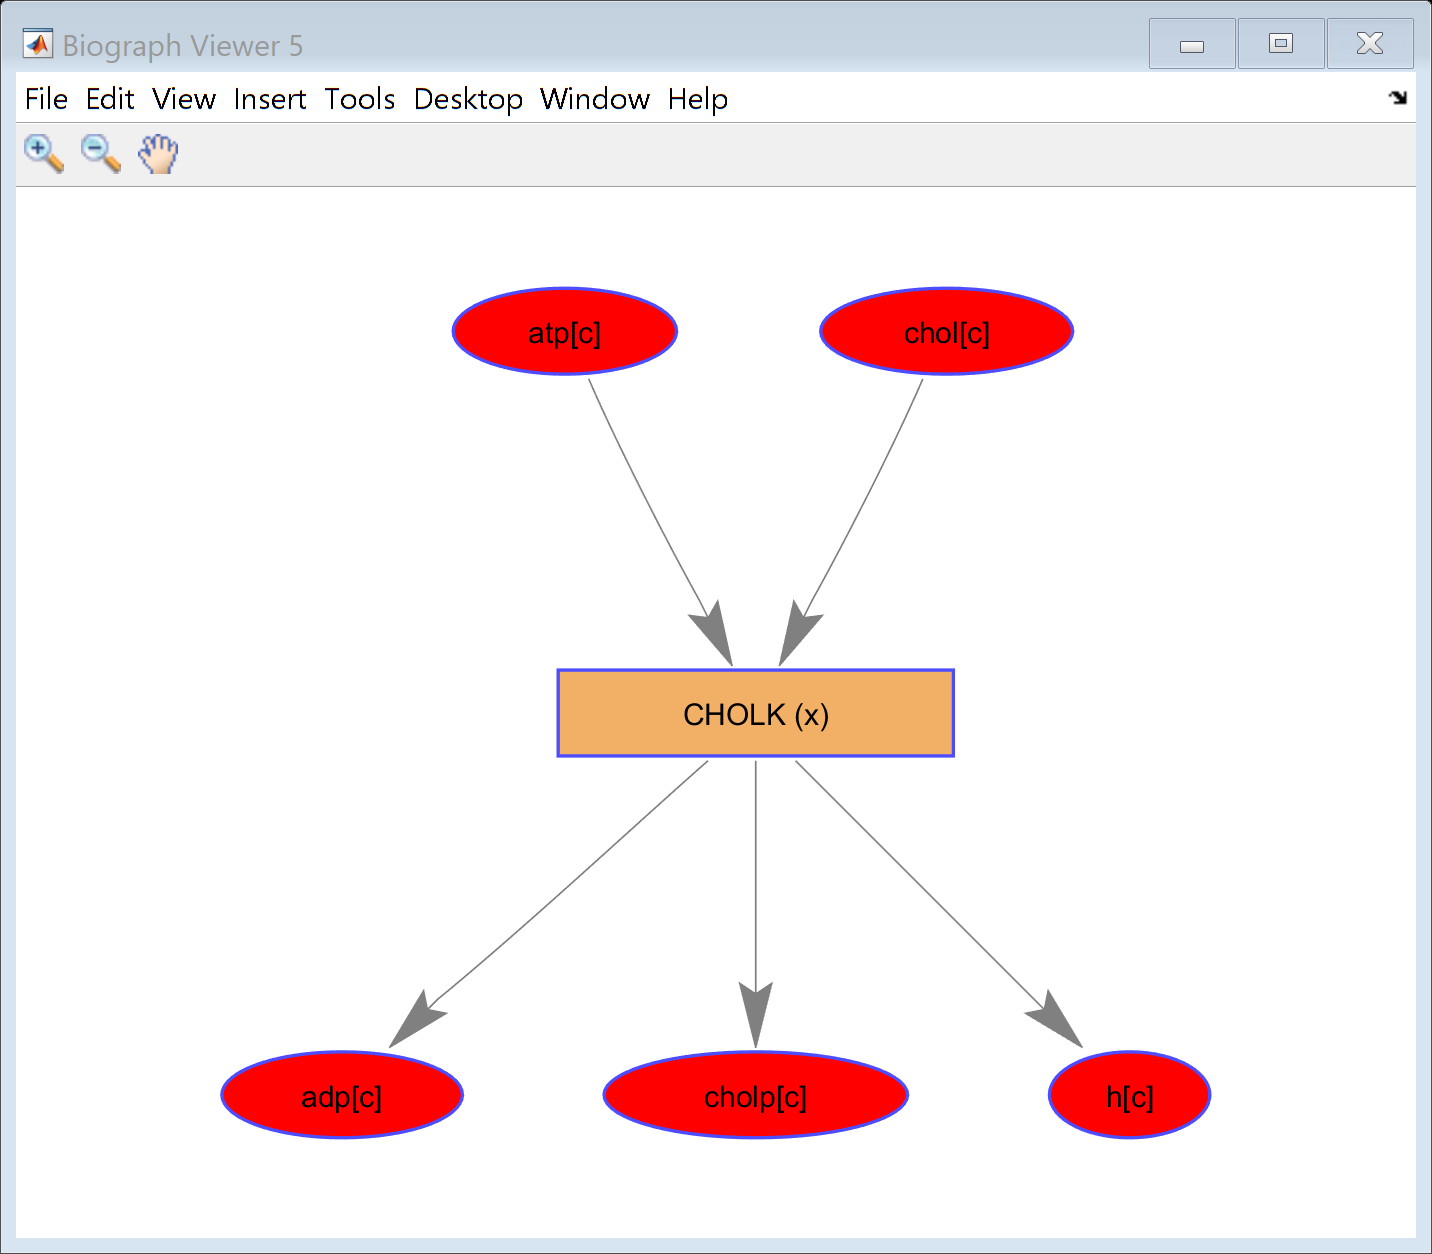

End_time = '2025_6_28_18_10_58.681'

Total_time = '0_0_0_0_0_2.098'

ans = 5×1 cell array
    {'adp[c]'  }
    {'atp[c]'  }
    {'chol[c]' }
    {'cholp[c]'}
    {'h[c]'    }


%Run until Section 2 of the normal and continue with this script (no need
%to do section 3 and 4)
% Finding reactions associated with a given gene is found
%change name of Rxn[HGNCno] for every new addition
RxnHGNC = findRxnsFromGenes(model, 'HGNC:1937')

Start_time = '2025_6_28_18_10_58.787'

Biograph object with 3 nodes and 2 edges.


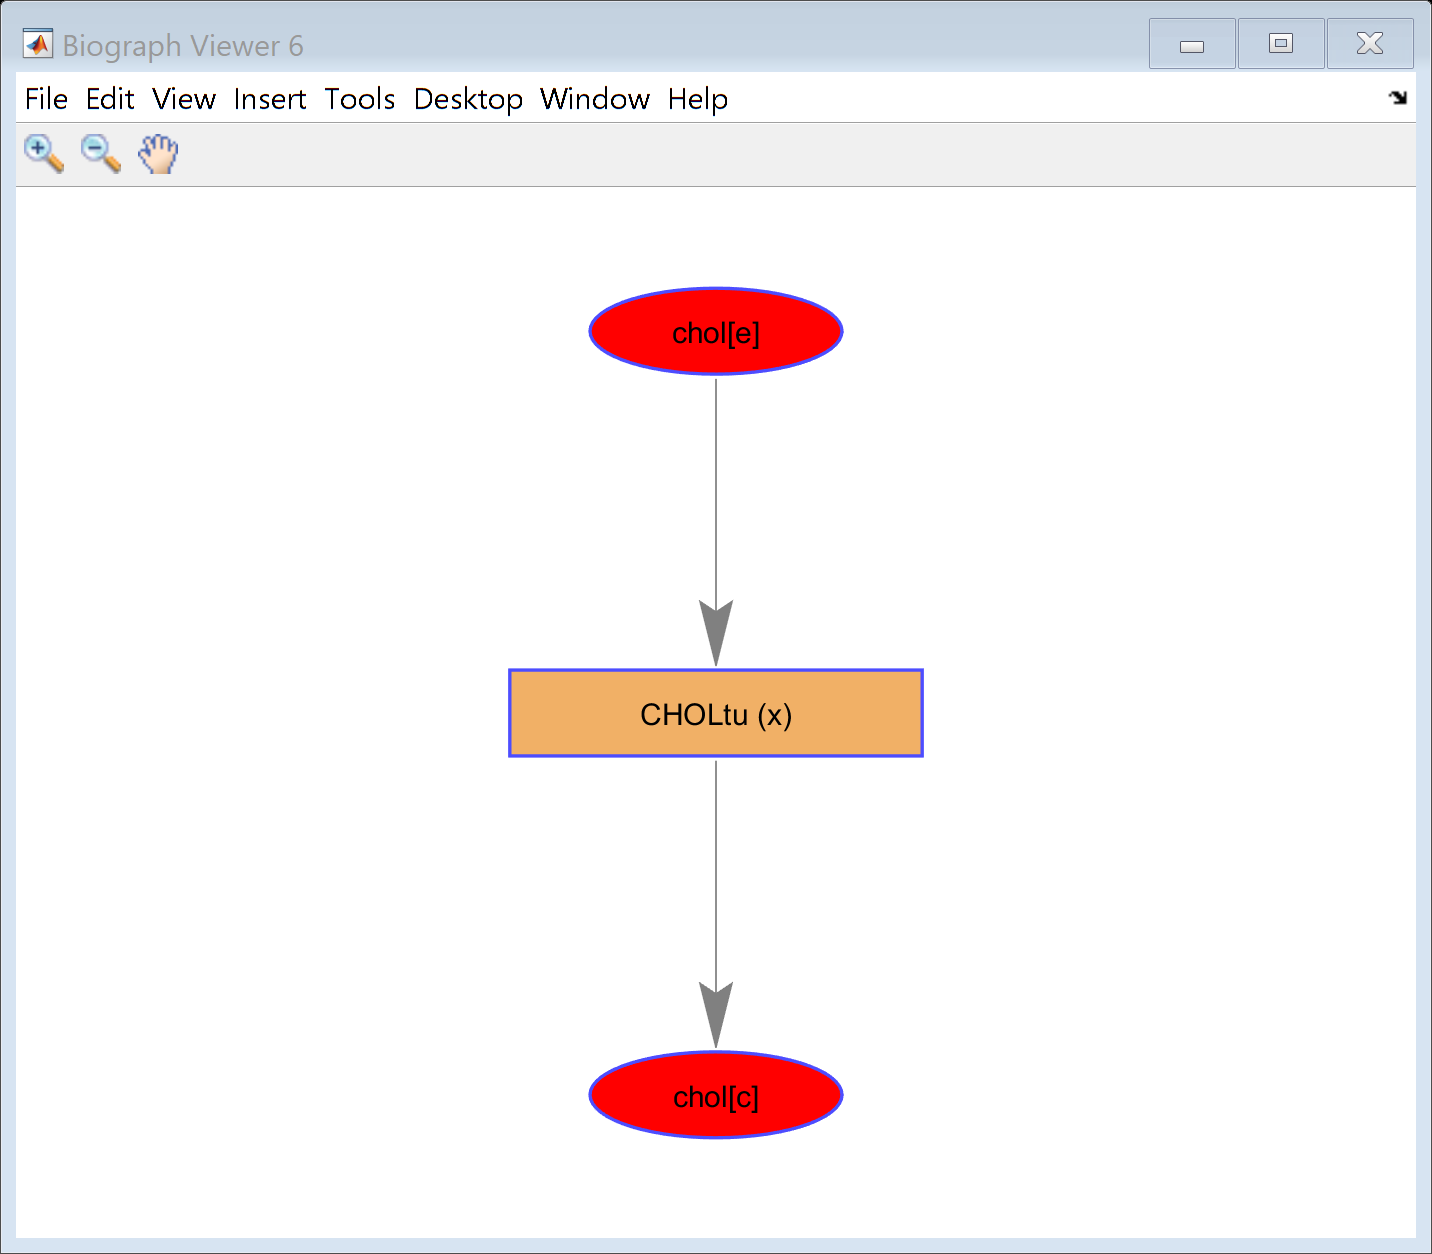

End_time = '2025_6_28_18_10_59.886'

Total_time = '0_0_0_0_0_1.099'

ans = 2×1 cell array
    {'chol[c]'}
    {'chol[e]'}


RxnHGNC = findRxnsFromGenes(model, 'HGNC:1938')

Start_time = '2025_6_28_18_10_59.956'

Biograph object with 5 nodes and 4 edges.


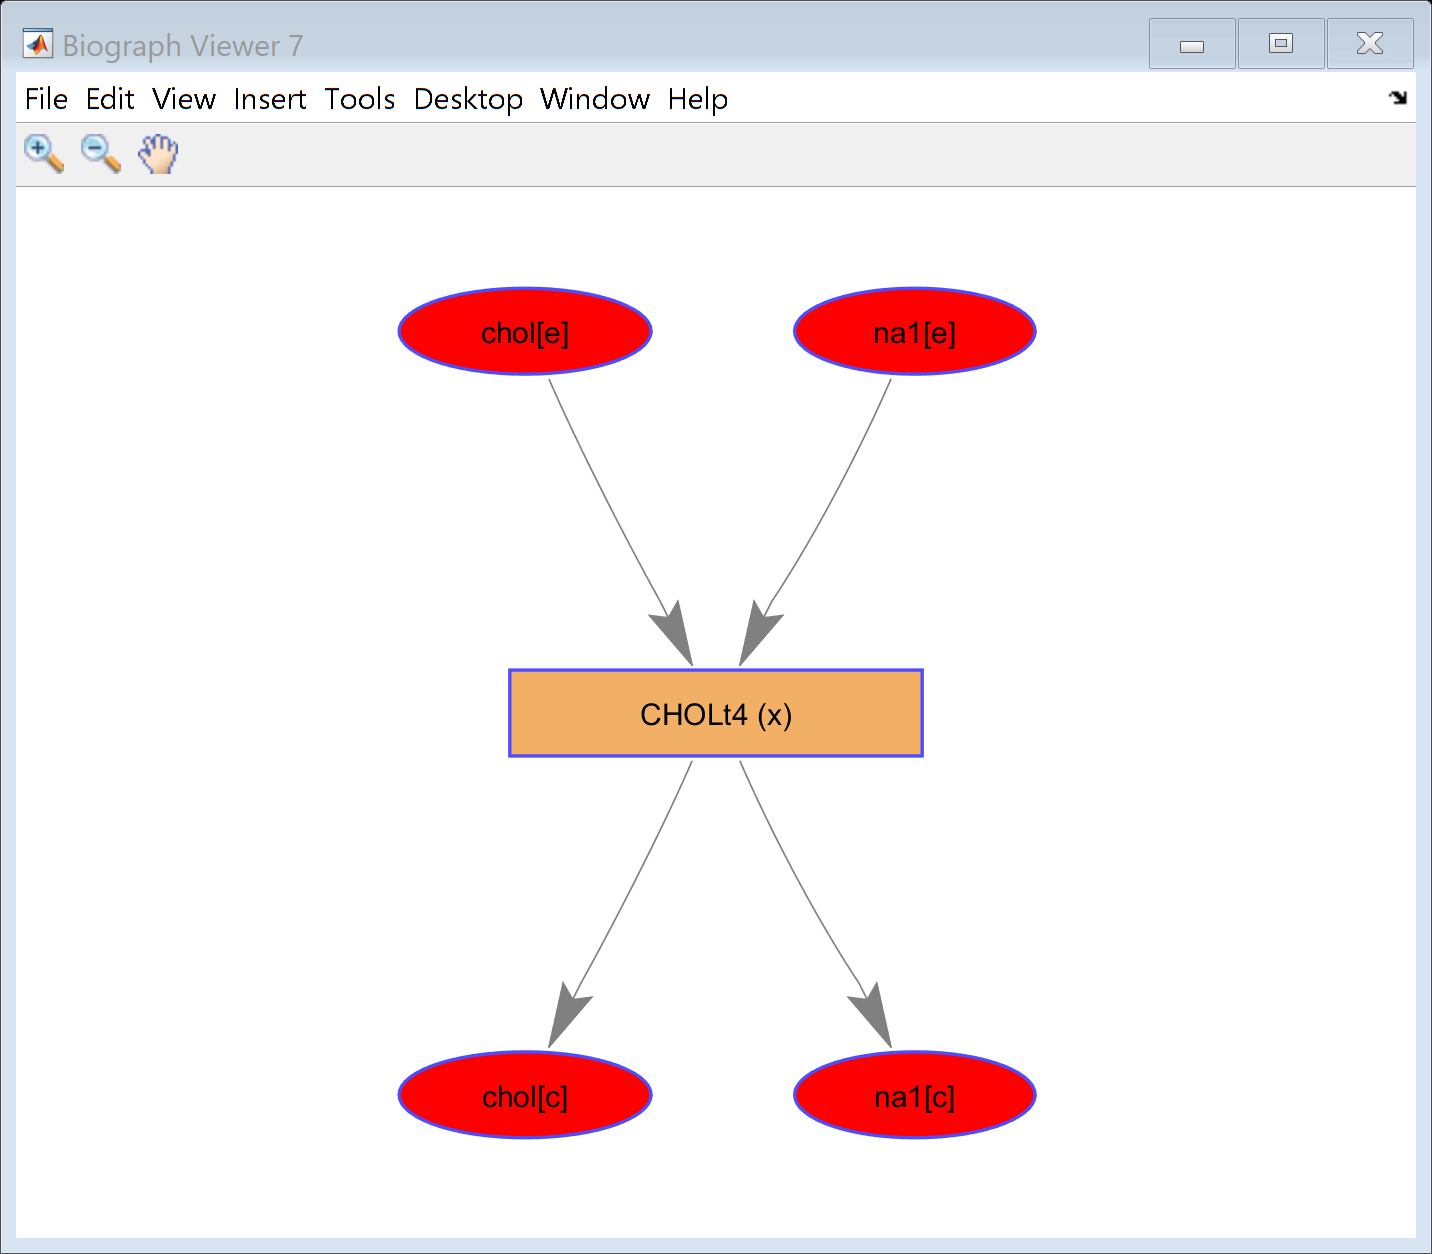

End_time = '2025_6_28_18_11_1.063'

Total_time = '0_0_0_0_1_-58.893'

ans = 4×1 cell array
    {'chol[c]'}
    {'chol[e]'}
    {'na1[c]' }
    {'na1[e]' }


RxnHGNC = findRxnsFromGenes(model, 'HGNC:10966')

Start_time = '2025_6_28_18_11_1.133'

Biograph object with 14 nodes and 16 edges.


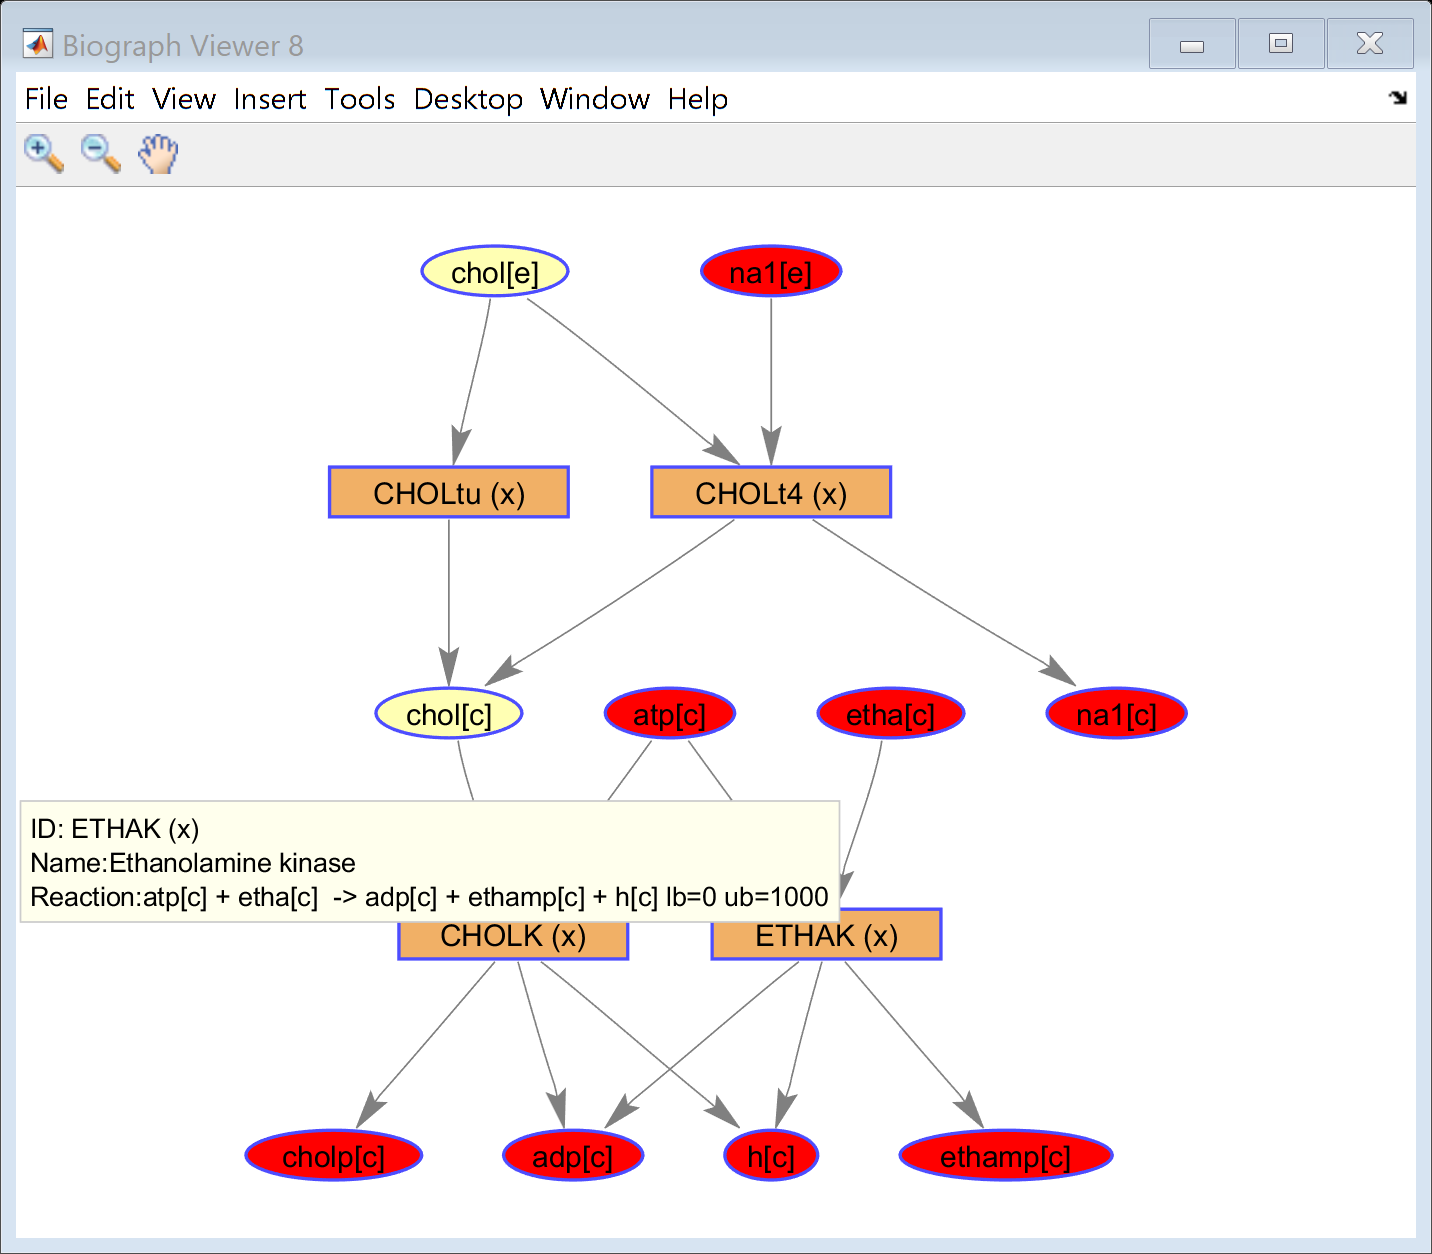

End_time = '2025_6_28_18_11_3.231'

Total_time = '0_0_0_0_0_2.098'

ans = 10×1 cell array
    {'adp[c]'   }
    {'atp[c]'   }
    {'chol[c]'  }
    {'chol[e]'  }
    {'cholp[c]' }
    {'etha[c]'  }
    {'ethamp[c]'}
    {'h[c]'     }
    {'na1[c]'   }
    {'na1[e]'   }


RxnHGNC = findRxnsFromGenes(model, 'HGNC:10969')
RxnHGNC = findRxnsFromGenes(model, 'HGNC:14025') 


Start_time = '2025_6_28_18_11_3.331'

Biograph object with 38 nodes and 46 edges.


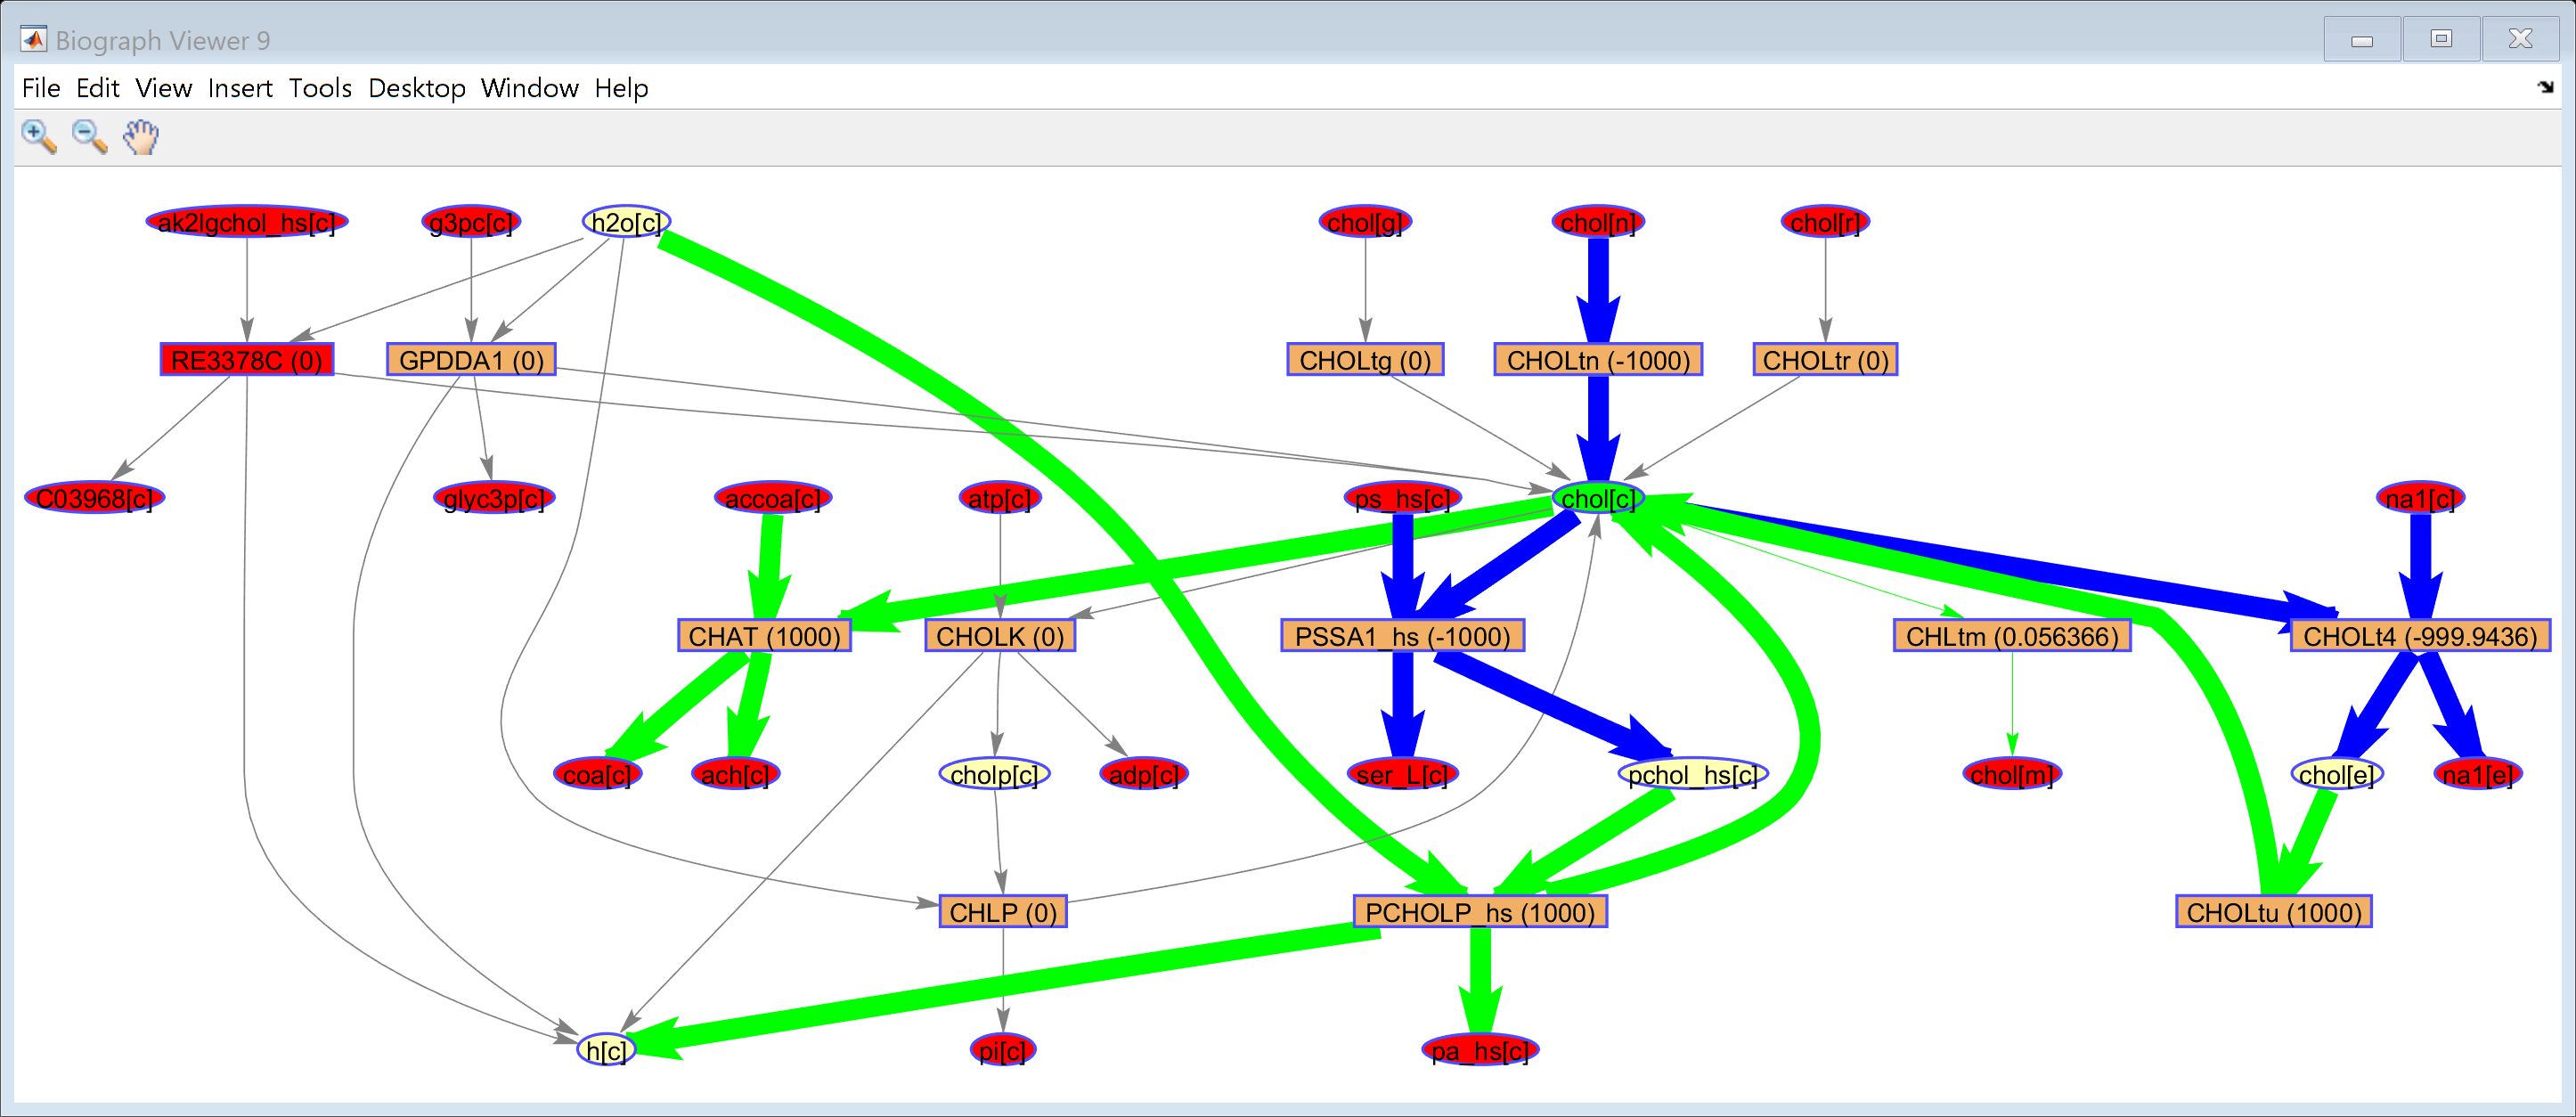

End_time = '2025_6_28_18_11_8.909'

Total_time = '0_0_0_0_0_5.578'

%Finding metabolites and reactions from a gene
MetHGNC = findMetsFromRxns(model, 'CHOLK')

MetHGNC = findMetsFromRxns(model, 'CHOLtu') 
MetHGNC = findMetsFromRxns(model, 'CHOLt4') 

Unable to resolve the name FBAanaerobC.v.

%Display said reaction
draw_by_rxn(model, {'CHOLK'},  'true' ,'both')
draw_by_rxn(model, {'CHOLtu'},  'true' ,'both')
draw_by_rxn(model, {'CHOLt4'},  'true' ,'both')
%shows both substrates and products resulting from reaction
%Show all, just add all reaction names, requires starting metabolite!!!!!
draw_by_rxn(model, {'CHOLtu', 'CHOLK', 'CHOLt4', 'ETHAK'}, 'true', 'both', 'chol[c]')
%Visualize with flux in aerobic
draw_by_met(model,{'chol[c]'},'true',1, 'struc', {''}, FBAaerobic.v);
%Visualize with flux in anaerobic
draw_by_met(model,{'chol[c]'},'true',1, 'struc', {''}, FBAanaerobC.v);
